# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 5

## 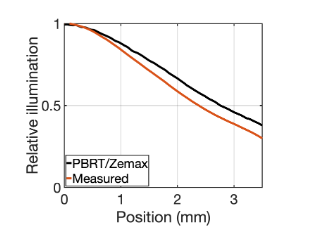

Fig. 5. Comparison of simulated and measured relative illumination. The curves show the relative illumination from the center of the sensor to a 3.5 mm field height (the sensor diagonal is 7 mm). The Zemax black box model relative illumination and ray-transfer prediction in PBRT are nearly identical (black). Neither closely matches the measured relative illumination (red), which falls-off more rapidly.

% Lens vignetting estimation

%% Initialize ISET and Docker
ieInit;
if ~piDockerExists, piDockerConfig; end

%%
tmp = load('p4aLensVignet_dc_inf_pos1.mat');

%%
RIpath = fullfile(cboxRootPath, 'data', 'lens',...
                        'zemax');
RIName = fullfile(RIpath, 'RI_data.txt');
RI = readmatrix(RIName);
lensVignetZemax = RI(:,1:2);
%%
thisR = piRecipeDefault('scene name', 'flat surface');

Read 1 materials.
Read 1 textures.
***Scene parsed.


thisR.set('lights', 'delete', 'all');
infLight = piLightCreate('inflight', 'type', 'infinite');
thisR.set('light', 'add', infLight);

%%
% Fast rendering setting
% {
thisR.set('film resolution',[4032 3024]/16);
nRaysPerPixel = 256;
thisR.set('rays per pixel',nRaysPerPixel);
thisR.set('nbounces', 2);
thisR.set('fov', 83);
thisR.set('film diagonal', 7.056); % mm
%}

%% Create lens
lensFile = fullfile(cboxRootPath, 'data', 'lens', 'pixel4a-rearcamera-ellipse-raytransfer.json');
cameraRTF = piCameraCreate('raytransfer','lensfile',lensFile);

camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


thisR.camera = cameraRTF;

%% Set film distance
filmDistOri = 0.464135918 + 0.001; % in meters
% filmDist = 0.49234;
filmDist = filmDistOri;
thisR.set('film distance', filmDist/1000);

piWrite(thisR);

Overwriting PBRT file /home/zhenglyu/git/iset3d/local/flatSurface/flatSurface.pbrt



[oiTemp, result] = piRender(thisR, 'render type', 'radiance', 'scale illuminance', false,...
                    'docker image','vistalab/pbrt-v3-spectral:raytransfer-ellipse');

Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/home/zhenglyu/git/iset3d/local/flatSurface" --volume="/home/zhenglyu/git/iset3d/local/flatSurface":"/home/zhenglyu/git/iset3d/local/flatSurface" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /home/zhenglyu/git/iset3d/local/flatSurface/renderings/flatSurface.dat /home/zhenglyu/git/iset3d/local/flatSurface/flatSurface.pbrt
*** Rendering time for flatSurface:  19.6 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.


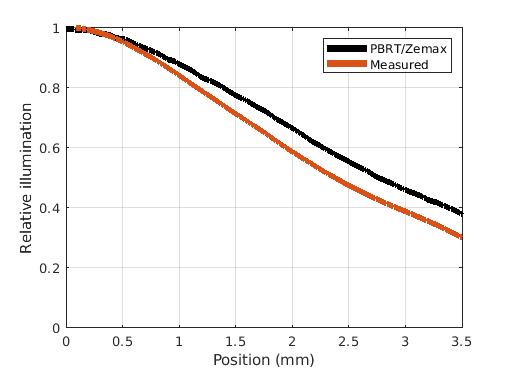

oiName = sprintf(['CBRTF_flatsurf_filmdist_' num2str(filmDist) 'mm']);
oiFlatSurface = oiSet(oiTemp, 'name', oiName);
oiFlatSurface = oiSet(oiFlatSurface, 'optics offaxismethod',  'skip');

%% Calculate before and after correction
sensorRTF = cbSensorCreate;
sensorRTF = sensorSet(sensorRTF, 'noise flag', -1);
sensorRTF = cbSensorCompute(sensorRTF, oiFlatSurface,...
                            'vignettcorrection', false);
voltsRTF = sensorGet(sensorRTF, 'volts');

[lensVignetNorm, ~] = cbVignettingFitting(voltsRTF(1:2:end, 1:2:end), 'type', 'sensor');
lensVignetFullRTF = imresize(lensVignetNorm, size(tmp.pixel4aLensVignetSlope));


sensorRTFCorr = cbSensorCompute(sensorRTF, oiFlatSurface,...
                            'vignettcorrection', true);

voltsRTFCorr = sensorGet(sensorRTFCorr, 'volts');
[lensVignetNorm, lensVignet] = cbVignettingFitting(voltsRTFCorr(1:2:end, 2:2:end), 'type', 'sensor');
lensVignetFullRTFCorr = imresize(lensVignetNorm, size(tmp.pixel4aLensVignetSlope));

%%
sz = size(lensVignetFullRTFCorr);
indexX = uint16(1:sz(2)/2);
indexY = uint16(0.75 * indexX);
filmHeight = (single(indexX).^2+single(indexY).^2).^0.5*1.4/1000;
ind = sub2ind(sz, indexY+sz(1)/2-1, indexX+sz(2)/2-1);
%% Compare with Zemax
ieNewGraphWin; hold all;
% Zemax & RTF
% plot(lensVignetZemax(:,1), lensVignetZemax(:,2), 'LineWidth', 8);
plot(filmHeig0;cht, lensVignetFullRTF(ind), 'k-', 'LineWidth', 5);
plot(filmHeight, tmp.pixel4aLensVignetSlope(ind), 'LineWidth', 5)
legend('PBRT/Zemax', 'Measured');
grid on; box on; ylim([0 1]); xlim([0 3.5]); xticks(0:1:3);yticks(0:0.5:1);
xlabel('Position (mm)'); ylabel('Relative illumination');